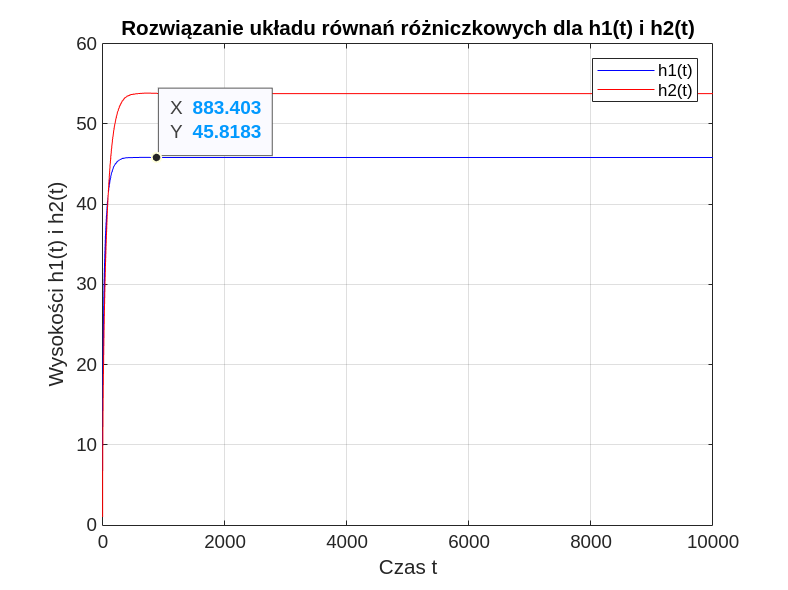

% Definiowanie stałej C1
C1 = 0.75; % przykładowa wartość, zmień ją zgodnie z zadaniem
C2 = 0.55;

alfa1 = 13;
alfa2 = 12;
tau = 120;

% Definiowanie funkcji F1(t), FD(t), i F2(h1)
F1_in = @(t)73;
F1 = @(t) F1_in(t - tau);     % przykład funkcji dopływu zależnej od czasu
FD = @(t) 15;               % przykład stałego dodatkowego dopływu
F2 = @(h1) alfa1 * h1^0.5;
F3 = @(h2) alfa2 * h2^0.5;

% Definiowanie równania różniczkowego jako funkcji anonimowej
odefun = @(t, y) [
    (F1(t) + FD(t) - F2(y(1))) / (2 * C1 * y(1));    % równanie dla dh1/dt
    (F2(y(1)) - F3(y(2))) / (2 * C2 * y(2))          % równanie dla dh2/dt
];


% Ustalanie początkowych warunków i zakresu czasu
h1_0 = 1;            % początkowa wartość h1
h2_0 = 1;            % początkowa wartość h2
tspan = [0, 10000];     % zakres czasu

% Rozwiązywanie układu równań za pomocą ode45
[t, y] = ode15s(odefun, tspan, [h1_0, h2_0]);

% Wykres wyników
figure;
plot(t, y(:, 1), 'b', 'DisplayName', 'h1(t)'); % wykres dla h1
hold on;
plot(t, y(:, 2), 'r', 'DisplayName', 'h2(t)'); % wykres dla h2
xlabel('Czas t');
ylabel('Wysokości h1(t) i h2(t)');
title('Rozwiązanie układu równań różniczkowych dla h1(t) i h2(t)');
legend;
grid on;
hold off;

xlim([0 10000]);
ylim([0.0 60.0]);
 
h1t = findobj(gcf, "DisplayName", "h1(t)");
datatip(h1t,925.1,45.82);

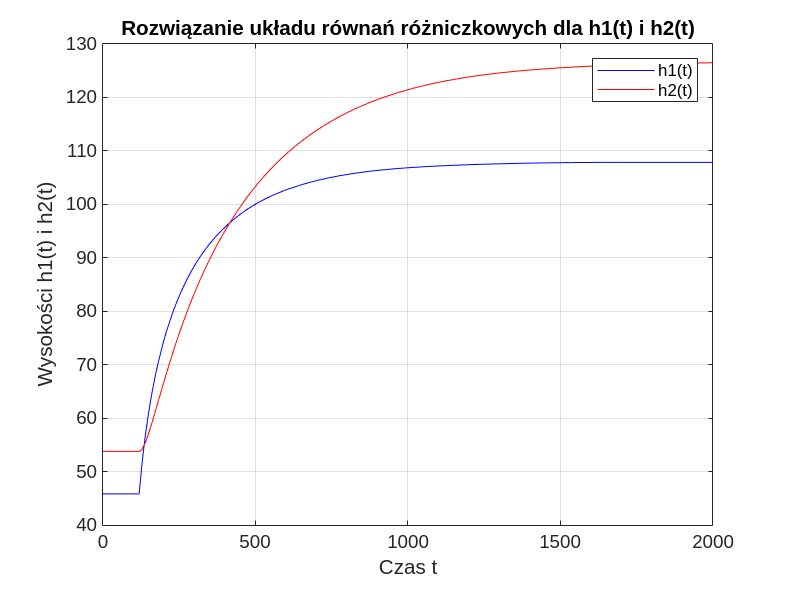


t_span = [1:2000];
F1_in = @(t)73;
tau = 120;
F1 = @(t) F1_in(t - tau);     % przykład funkcji dopływu zależnej od czasu
FD = @(t) 15;
h1_0 = 45.8225;            
h2_0 = 53.7778; 


[t, h] = nonlinear_tank_model(t_span, h1_0, h2_0, 120, 15);

figure;
plot(t, h(:, 1), 'b', 'DisplayName', 'h1(t)'); % wykres dla h1
hold on;
plot(t, h(:, 2), 'r', 'DisplayName', 'h2(t)'); % wykres dla h2
xlabel('Czas t');
ylabel('Wysokości h1(t) i h2(t)');
title('Rozwiązanie układu równań różniczkowych dla h1(t) i h2(t)');
legend;
grid on;
hold off;

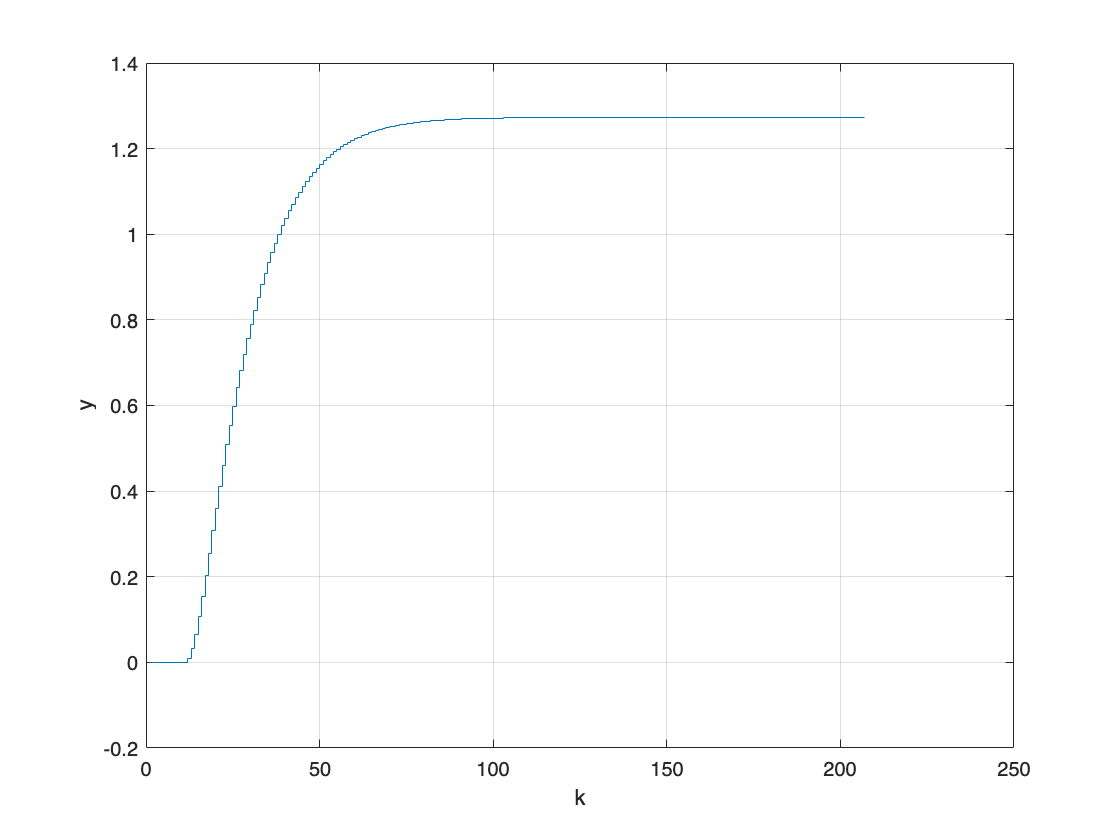

clear;
t_step  = 200;
Ts = 10;
h2_0 = 53.7778; 
Upp = 73;
s = get_s_lin_v2(t_step, Ts, h2_0, Upp );
figure;
stairs(1:length(s), s);
xlabel('k');
ylabel('y');
grid on;
exportgraphics(gcf,fullfile('wykresy', 'zad1_s.png'));

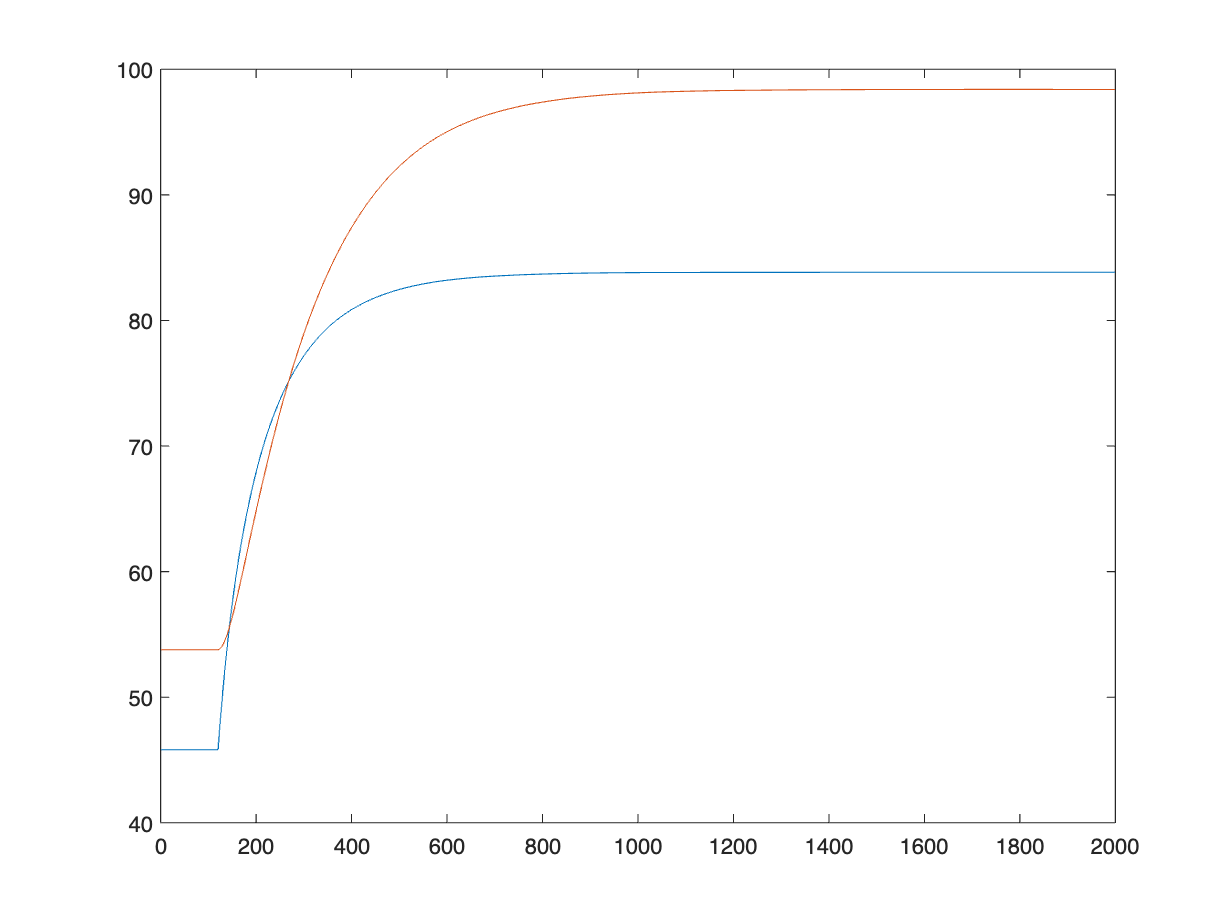

    clear;
    t_span = 1:2000;
    FDpp = 15;
    Upp =73;            
    h2_0_lin = 53.7778; 
    Ts = 10;

    alfa1 = 13;
    alfa2 = 12;

    h1_0_lin = h2_0_lin * (alfa2 / alfa1)^2;

    u_signal = ones(floor(length(t_span)/Ts), 1) * 1.5*Upp;
    z_signal = ones(floor(length(t_span)/Ts), 1) * 15;


    [~, h] = linear_tank_model_v2(t_span, h1_0_lin, h2_0_lin, h2_0_lin, Ts, Upp, FDpp, u_signal, z_signal);

    stairs(h);

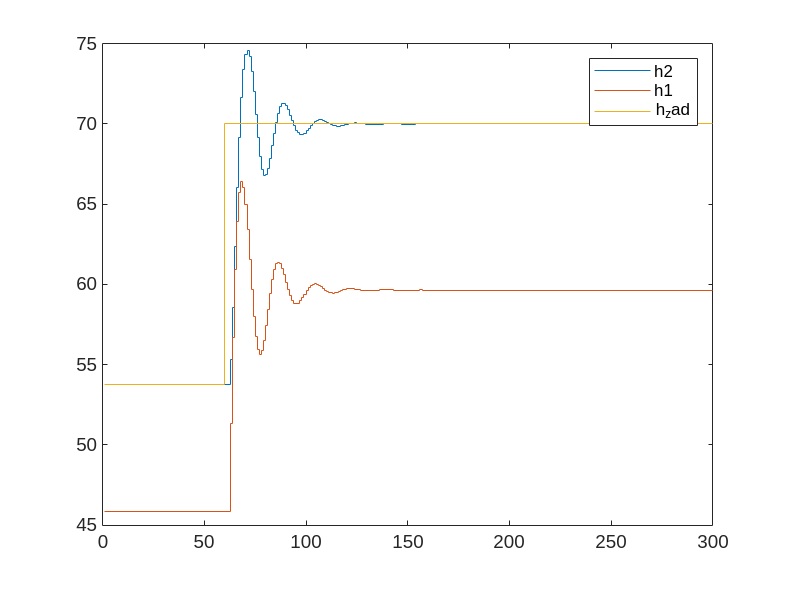

%Zadanie 1 - DMC
D = 50; N = 30; Nu = 5; lambda = 1; Ts = 40; t_span = 1:Ts;

tau = 120;
FD = @(t) 15;

kk =300; ks = 60;
Upp = 73;
h1_0 = 45.8225;            
h2_0 = 53.7778;

[M, Mp, K, ke, Ku] = offline_DMC(s, D, N, Nu, lambda);

h_zad(1:ks-1) = h2_0; h_zad(ks:kk) = 70; 

h1(1:ks-1) = h1_0;
h1(ks:kk) = 0;
h2(1:ks-1) = h2_0;
h2(ks:kk) = 0;
u(1:ks-1) = Upp;
u(ks:kk) = 0;
e(1:kk) = 0;
delta_u(1:kk) = 0;

% min_delta_u = -1.000000e-01;
% max_delta_u = 1.000000e-01;
% 
% min_u = 0.6;
% max_u = 1.2;

for k = ks:kk

    F1 = @(t) u(k - tau/Ts);
    [~, h] = nonlinear_tank_model(t_span, h1_0, h2_0, F1, FD);

    h1(k) = h(end,1); 
    h2(k) = h(end,2);
    h1_0 = h1(k);
    h2_0 = h2(k);


    e(k) = h_zad(k) - h2(k);

    delta_sum = 0;
    for j = 1:D-1
        delta_sum = delta_sum + Ku(j)*delta_u(k-j);
    end

    delta_u(k) = ke*e(k) - delta_sum;
    % delta_u(k) = min(max(delta_u(k), min_delta_u), max_delta_u);

    u(k) = delta_u(k) + u(k-1);
    % u(k) = min(max(u(k), min_u), max_u);
end

figure;
stairs(h2);
hold on
stairs(h1);
stairs(h_zad);
legend('h2', 'h1','h_zad')
hold off

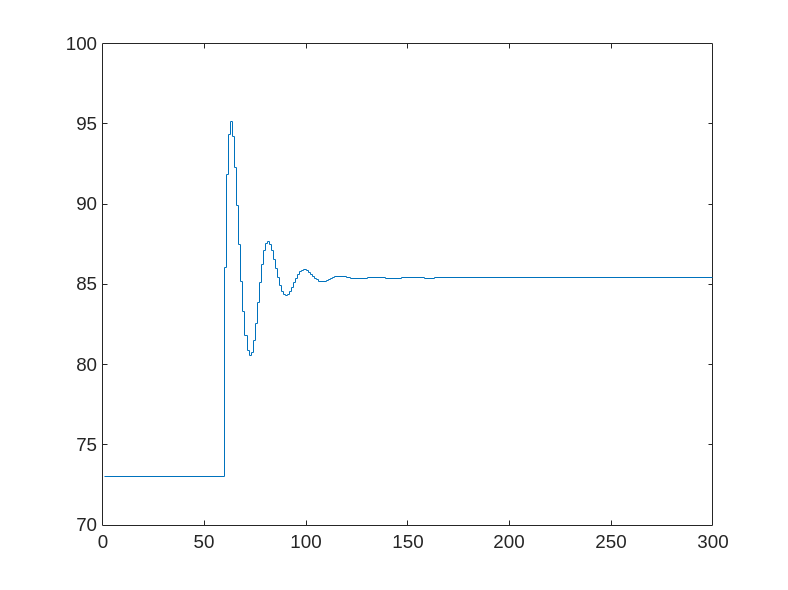

figure;
stairs(u);